# Load data

%% Data has been pre-loaded into matlab and converted into a .mat data struct with fields: Fs, EEG
uiopen(".mat");

## Separate channels - PSG

[L, epochsize, ~] = size(Data.EEGPSG);
PSG_m = zeros(L, epochsize);
% EEG_m = Data.EEGPSG(:,:,1);
for i= 1:1:L
    if std(Data.EEGPSG(i,:,1))<std(Data.EEGPSG(i,:,2))
        PSG_m(i,:) = Data.EEGPSG(i,:,1);
    else
        PSG_m(i,:) = Data.EEGPSG(i,:,2);
    end
end
Fs = Data.FsPSG;

Fs = 250

EEG_m = PSG_m;
EEG = reshape(EEG_m',[],1)';

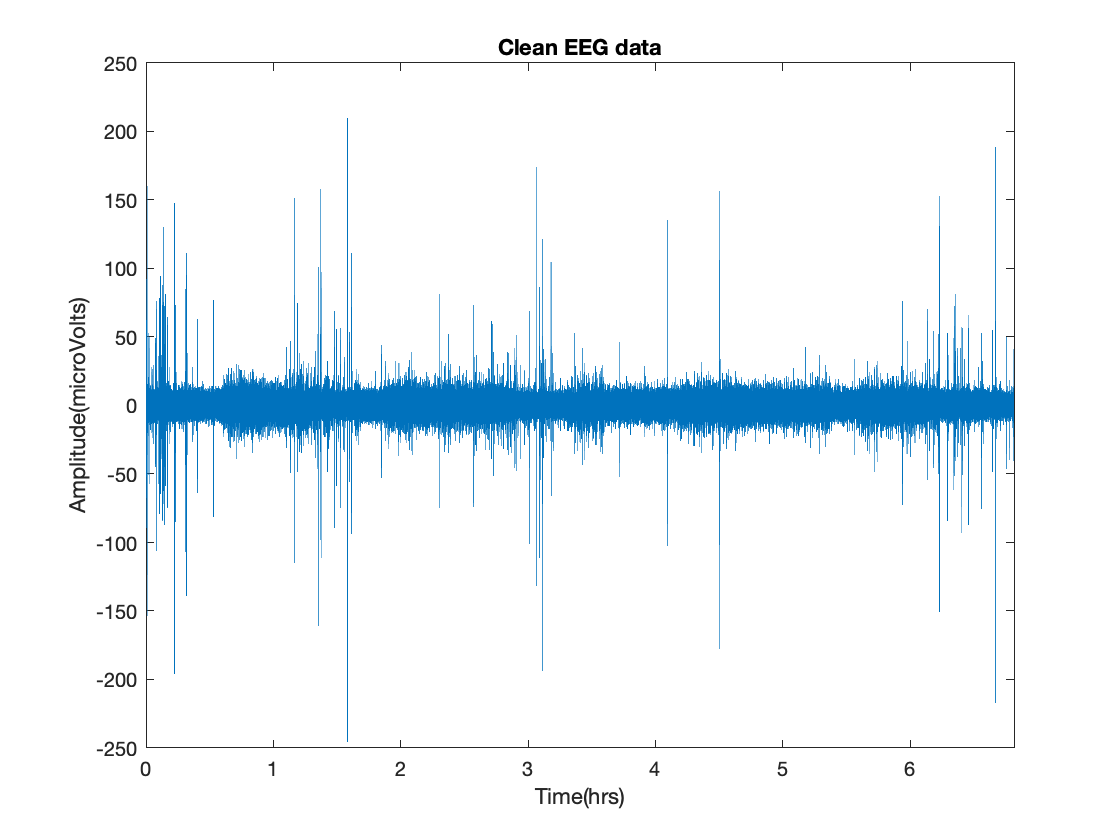

figure;
t = (1:1:length(EEG))/Fs/3600;
plot(t, EEG);
xlabel("Time(hrs)");
ylabel("Amplitude(microVolts)");
title("Clean EEG data");
xlim([0,length(EEG)/Fs/3600]);

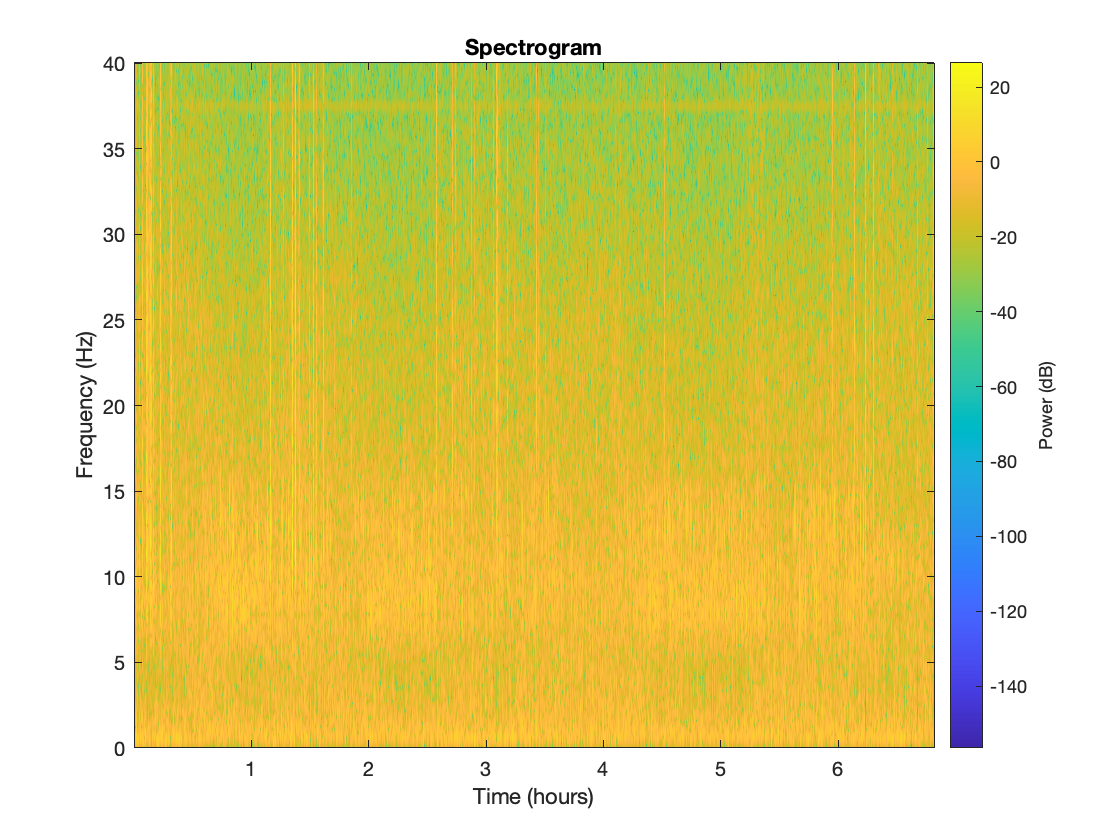

figure
pspectrum(EEG,Fs,'spectrogram','FrequencyLimits',[0, 40], "FrequencyResolution", 0.5)
title("Spectrogram");

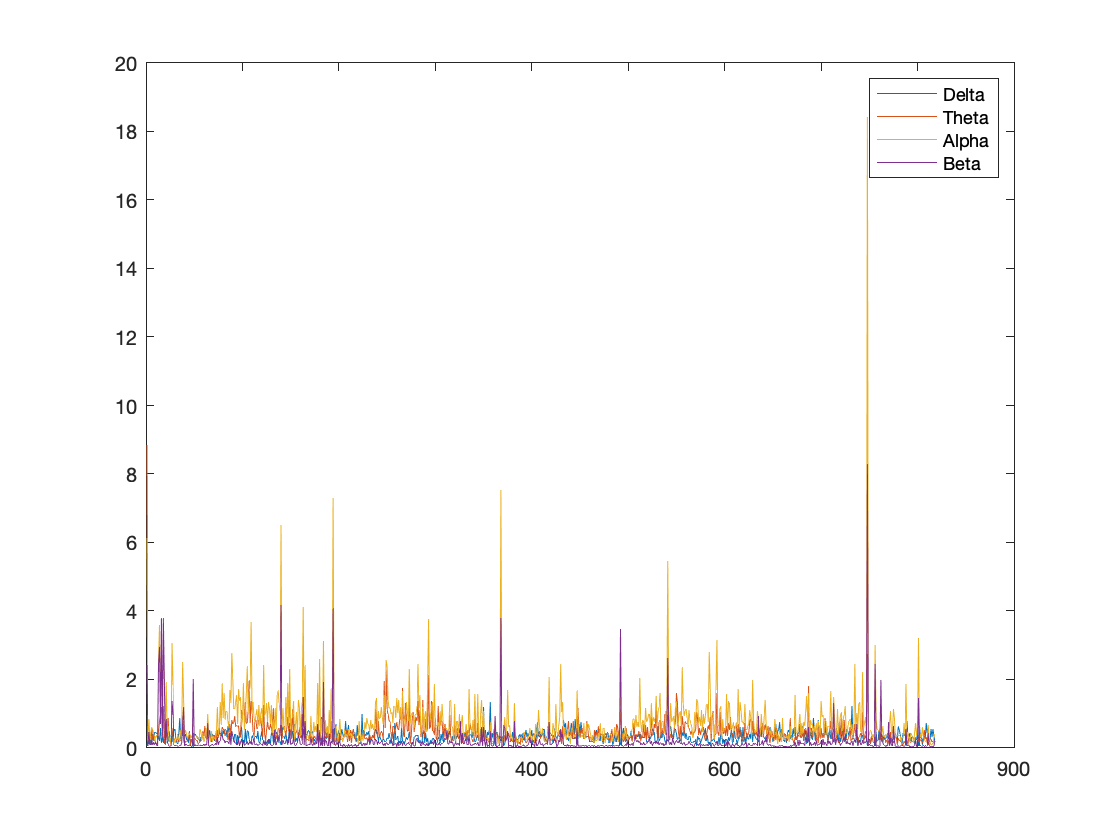

[s, f, t, p] = spectrogram(EEG, epochsize, 0, (1:0.5:40), Fs,'yaxis');
del = sum(p(1:8,:))/8;
the = sum(p(8:16,:))/8;
alp = sum(p(16:24,:))/8;
bet = sum(p(24:60,:))/36;
figure;
plot(del);
hold on
plot(the);
hold on
plot(alp);
hold on
plot(bet);
legend("Delta", "Theta", "Alpha", "Beta");

## wavelet analysis

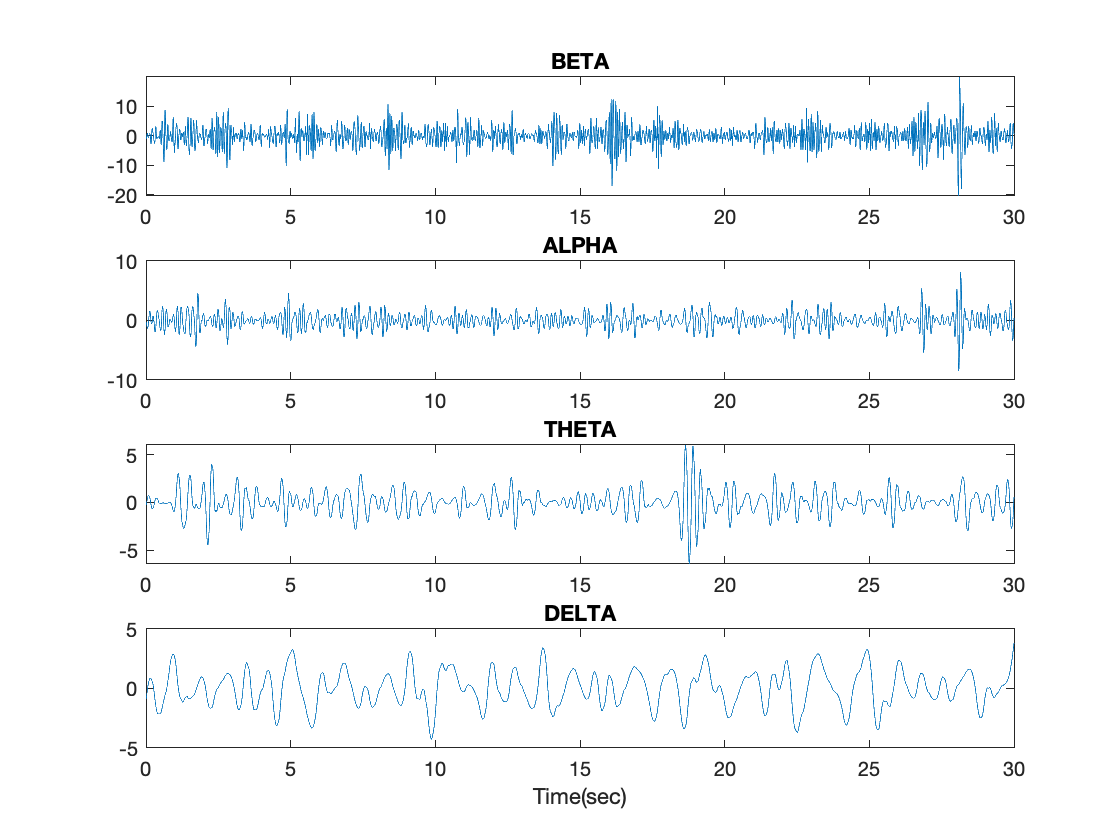

epo = 251;
s = EEG_m(200,:);
N = length(s);

% Define the wavelet's name and the level for decomposition
waveletName='db5';
level=6;
% Multilevel 1-D wavelet decomposition for channel 0
[c,l]=wavedec(s,level,waveletName);
% Beta Alpha Theta
[~,~,~,cd4,cd5,cd6] = detcoef(c,l,[1 2 3 4 5 6]);
ca6 = appcoef(c,l,waveletName,6); % DELTA
 
% Reconstruct single branch from 1-D wavelet coefficients
 D4 = wrcoef('d',c,l,waveletName,4); % BETA 
 D5 = wrcoef('d',c,l,waveletName,5); % ALPHA 
 D6 = wrcoef('d',c,l,waveletName,6); % THETA 
 A6 = wrcoef('a',c,l,waveletName,6); % DELTA

 t = 1/Fs:1/Fs:epochsize/Fs;
 
figure;
           
Beta = D4;
subplot(4,1,1);
plot(t, Beta);
title('BETA');
                     
Alpha = D5;
subplot(4,1,2);
plot(t,Alpha); 
title('ALPHA'); 
            
Theta = D6;
subplot(4,1,3); 
plot(t,Theta);
title('THETA');
            
Delta = A6;
subplot(4,1,4);
plot(t,Delta);
title('DELTA');
xlabel("Time(sec)");

sig = EEG_m;
[L,~] = size(sig);
pAlpha = zeros(1,L);
pBeta = zeros(1,L);
pTheta = zeros(1,L);
pDelta = zeros(1,L);
del_amp = zeros(1,L);
waveletName='db5';
level=6;
for epo = 1:1:L
    s = sig(epo,:);
    % Multilevel 1-D wavelet decomposition
    [c,l] = wavedec(s,level,waveletName);
    % Reconstruct single branch from 1-D wavelet coefficients
    Beta = wrcoef('d',c,l,waveletName,4); % BETA 
    Alpha = wrcoef('d',c,l,waveletName,5); % ALPHA 
    Theta = wrcoef('d',c,l,waveletName,6); % THETA 
    Delta = wrcoef('a',c,l,waveletName,6); % DELTA
    
    del_amp(1,epo) = mean(abs(Delta));
    
    pDelta(1,epo) = pow2db(bandpower(Delta));
    pTheta(1,epo) = pow2db(bandpower(Theta));
    pAlpha(1,epo) = pow2db(bandpower(Alpha));
    pBeta(1,epo) = pow2db(bandpower(Beta));
end

spDelta = smooth(pDelta,0.01);
spTheta = smooth(pTheta,0.01);
spAlpha = smooth(pAlpha,0.01);
spBeta = smooth(pBeta,0.01);
del_amp = smooth(del_amp,0.01);

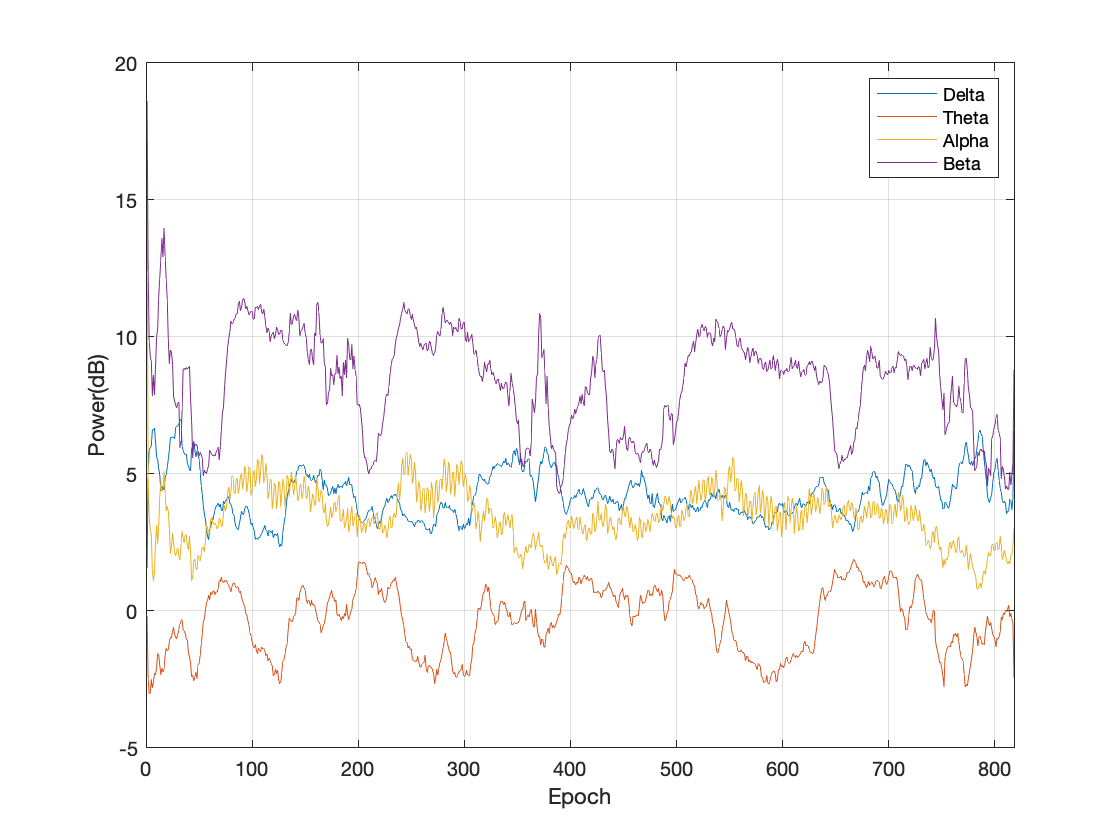

tL = (1:1:L);
figure;
plot(tL, spDelta);
hold on
plot(tL, spTheta);
hold on
plot(tL, spAlpha);
hold on
plot(tL, spBeta);
legend("Delta", "Theta", "Alpha", "Beta");
xlabel("Epoch");
ylabel("Power(dB)");
xlim([0, L])
grid on
hold off

ThD = mean(spDelta) + std(spDelta)/2;
ThB = mean(spBeta) + std(spBeta)/2;
ThA = mean(spAlpha) + std(spAlpha)/2;
class = [];
class_psg = [];
for i = 1: L
    if ((spDelta(i) > spAlpha(i) && spDelta(i) > spBeta(i)) && i > L*0.1 && i < L*0.9)
        class(i) = 2;
    elseif (spBeta(i) > spDelta(i)) && (spBeta(i) > spTheta(i))
        class(i) = 0;
    else
        class(i)=1;
    end
    if ((spDelta(i) >= ThD || (del_amp(i)>ThA)) && i > L*0.1 && i < L*0.9) 
        class(i) = 2;
    elseif (spBeta(i) >= ThB)
        class(i) = 0;
    else
        class(i)=1;
    end
    if (Data.Hyp(i) == 3)
        class_psg(i) = 2;
    elseif (Data.Hyp(i) == 0)
        class_psg(i) = 0;
    else
        class_psg(i) = 1;
    end
end


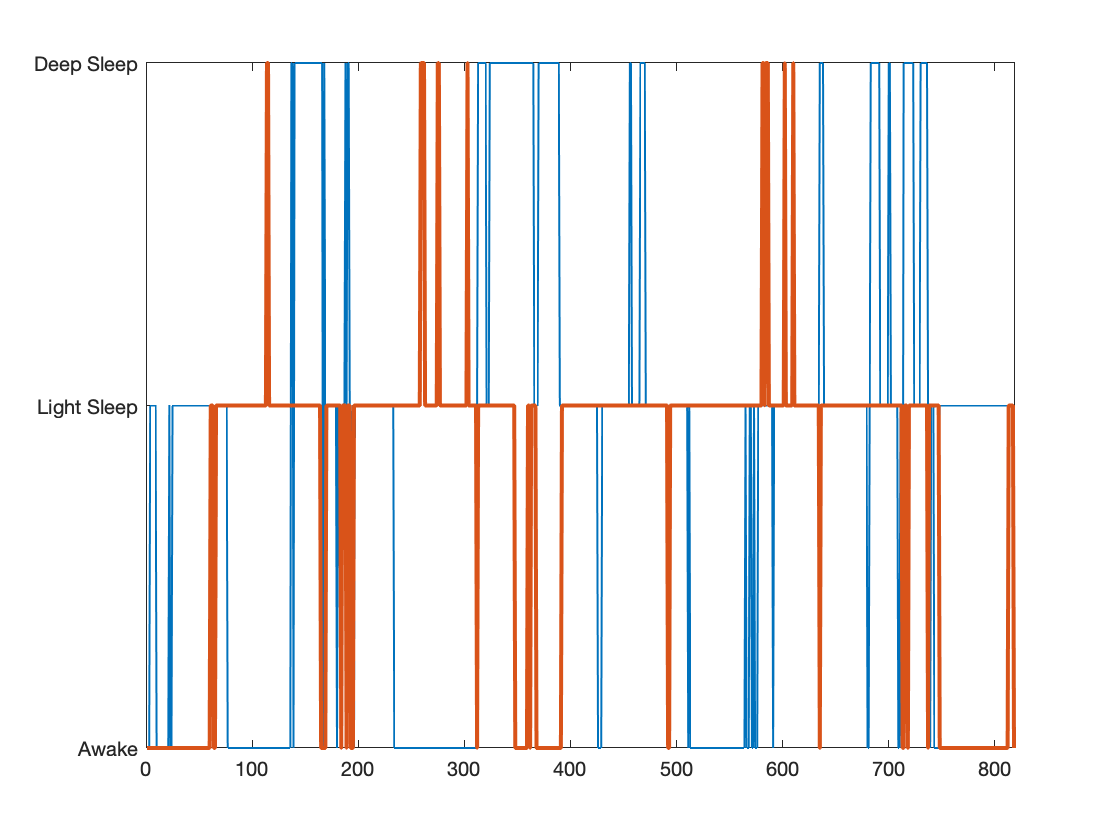

figure;
plot(tL,class,"LineWidth",1);
hold on
plot(tL,class_psg,"LineWidth",2);
hold off
xlim([0,L]);
yticks([0 1 2]);
yticklabels({'Awake', 'Light Sleep', 'Deep Sleep'});